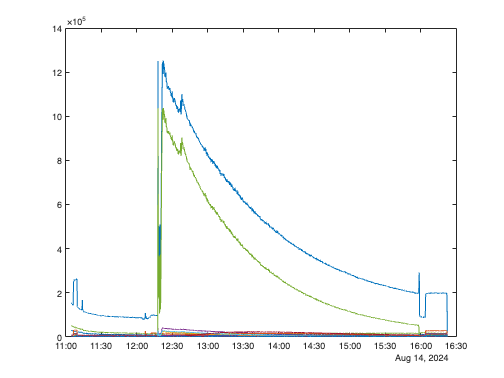

data1_table = readtable("all_Mx_data_HR.csv",'VariableNamingRule','preserve') ;
time1_table = readtable("all_tseries.csv");
daqdata_table1 = readtable("Heptanone_24-08-14_1202.xlsx",'VariableNamingRule','preserve') ;   
daqdata_table2 = readtable("Heptanone_24-08-14_1302.xlsx",'VariableNamingRule','preserve') ; 
daqdata_table3 = readtable("Heptanone_24-08-14_1402.xlsx",'VariableNamingRule','preserve') ; 
daqdata_table4 = readtable("Heptanone_24-08-14_1502.xlsx",'VariableNamingRule','preserve') ; 
time_daq = [daqdata_table1.Time ; daqdata_table2.Time ; daqdata_table3.Time ; daqdata_table4.Time] ; 
ozonev_daq = [daqdata_table1.Voltage_O3 ; daqdata_table2.Voltage_O3 ; daqdata_table3.Voltage_O3 ; daqdata_table4.Voltage_O3] ;
time_daq.Year = 2024 ; 
time_daq.Month = 08 ;
time_daq.Day = 14 ;
data1 = table2array(data1_table) ;
time1 = table2array(time1_table) - hours(7) ;
%plot native
plot(time1,data1)





% acetonitrile injection
inject1_time = '08/14/2024 12:06:00.000' ; 
inject1_diff = abs(inject1_time - time1) ; 
[~,inject1] = min(inject1_diff) ;

% 4-heptanone injection
inject2_time = '08/14/2024 12:17:00.000' ; 
inject2_diff = abs(inject2_time - time1) ; 
[~,inject2] = min(inject2_diff) ;

% light on
lighton_time = '08/14/2024 12:36:00.000' ; 
lighton_diff = abs(lighton_time - time1) ; 
[~,lighton] = min(lighton_diff) ;

% light off
lightoff_time = '08/14/2024 15:57:00.000' ; 
lightoff_diff = abs(lightoff_time - time1) ; 
[~,lightoff] = min(lightoff_diff) ;

%voltage scan start and end
vstart_time = '' ; 
vend_time = '' ; 
ind_vstart = find(time1(inject1:end) == vstart_time) ; 
ind_vend = find(time1(inject1:end) == vend_time) ;



% 0 air turned on
sample_end = '08/14/2024 15:58:00.100' ; 
sample_end_diff = abs(sample_end - time1) ; 
[~,endsample] = min(sample_end_diff) ;

%background before injections
bg_start_time = '08/14/2024 11:20:01.100' ; 
bg_end_time = '08/14/2024 12:00:00.100'; 
bg_start_diff = abs(bg_start_time - time1) ; 
[~,bg_start] = min(bg_start_diff) ;  
bg_end_diff = abs(bg_end_time - time1) ; 
[~,bg_end] = min(bg_end_diff) ;

%define var same duration as background subtracted data variable
time1_bgv = time1(inject1:endsample) ;
%define var same duration as background subtracted data variable
time1_bgv = time1(inject1:endsample) ;

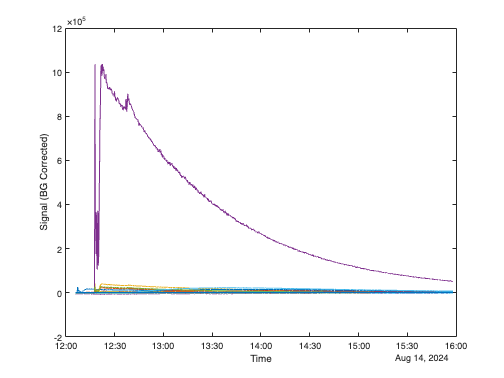


%% CLEAN UP DATA
%subtract backgrounds from data
bg_all = mean(data1(bg_start:bg_end,:)) ;
data1_bgcorr = data1(inject1:endsample,:) - bg_all ;

%define var same duration as background subtracted data variable
time1_bgv = time1(inject1:endsample) ;

%take out major reagent ions for plotting purposes
mass_plot = [1:1:396] ; 
mass_del = [1 53 71 64 96 112 278 277 40 76] ; 
mass_plot(mass_del) = [ ] ;

%take out voltage scan period


%plot inline
plot(time1_bgv,data1_bgcorr(:,mass_plot))
xlabel('Time') 
ylabel('Signal (BG Corrected)')

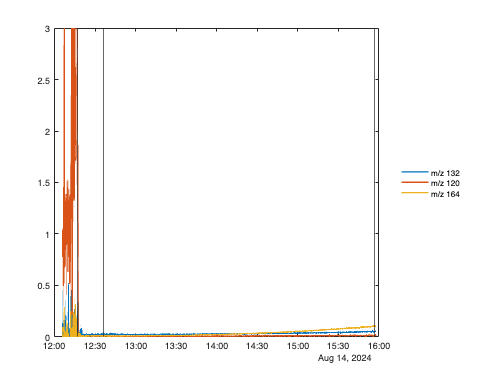


data_dilcorr = [ ] ; 
data_dilcorr = data1_bgcorr./data1_bgcorr(:,40) ;

%plot inline
plot(time1_bgv,data_dilcorr(:,130), 'LineWidth', 1.5) % C7H14ONH4+ 
hold on
plot(time1_bgv,data_dilcorr(:,118), 'LineWidth', 1.5) % C4H6O3NH4+
plot(time1_bgv,data_dilcorr(:,162), 'LineWidth', 1.5) % C7H14O3NH4+
xline(datetime(inject2_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
xline(datetime(lighton_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
xline(datetime(lightoff_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
legend('m/z 132','m/z 120','m/z 164','box','off','location','eastoutside') 
ylim([0 3])

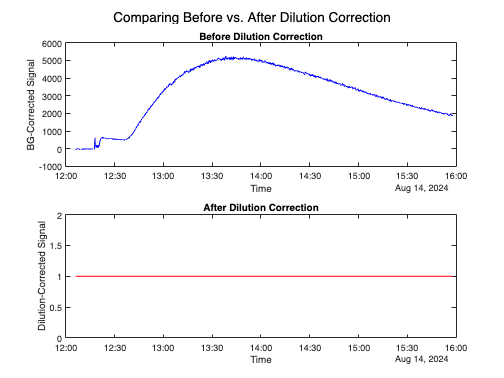

figure;

% Plot BEFORE dilution correction (40)
subplot(2,1,1);
plot(time1_bgv, data1_bgcorr(:,40), 'b'); 
xlabel('Time');
ylabel('BG-Corrected Signal');
title('Before Dilution Correction');

% Plot AFTER dilution correction
subplot(2,1,2);
plot(time1_bgv, data_dilcorr(:,40), 'r'); 
xlabel('Time');
ylabel('Dilution-Corrected Signal');
title('After Dilution Correction');

sgtitle('Comparing Before vs. After Dilution Correction');
hold off

# **HCA CLUSTERING**

max_all_masses = max(data_dilcorr) ; % max value each mass

% Find indices for the clustering range
lighton_time = datetime('08/14/2024 12:36:00.000', 'InputFormat', 'MM/dd/uuuu HH:mm:ss.SSS');
sample_end = datetime('08/14/2024 15:56:00.100', 'InputFormat', 'MM/dd/uuuu HH:mm:ss.SSS');

% Find nearest indices for the clustering range
lighton_diff = abs(time1_bgv - lighton_time);
[~, ind_lighton] = min(lighton_diff);

sample_end_diff = abs(time1_bgv - sample_end);
[~, ind_sample_end] = min(sample_end_diff);

% Extract data only within the range of interest: after lights turned on to
% before 0 air
hca_traces = data_dilcorr(ind_lighton:ind_sample_end, mass_plot) ./ max_all_masses(mass_plot);

% make sure no NaN values seen
disp(any(isnan(hca_traces(:)))) % Should return 0

   0




%  distances + clustering
distance = pdist(hca_traces', '@naneucdist');
Z = linkage(distance, 'weighted');
c = cophenet(Z, distance);
disp(['Cophenetic correlation coefficient: ', num2str(c)])

Cophenetic correlation coefficient: 0.94936


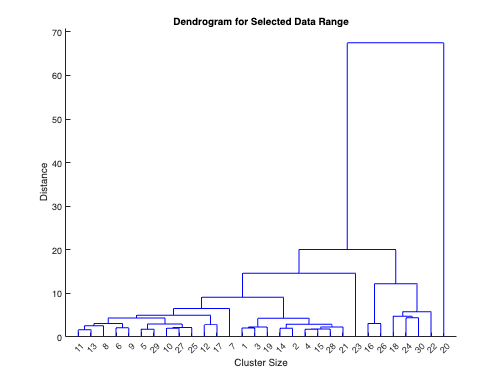


% Plot dendrogram
figure;
dendrogram(Z);
xlabel('Cluster Size');
ylabel('Distance');
title('Dendrogram for Selected Data Range');

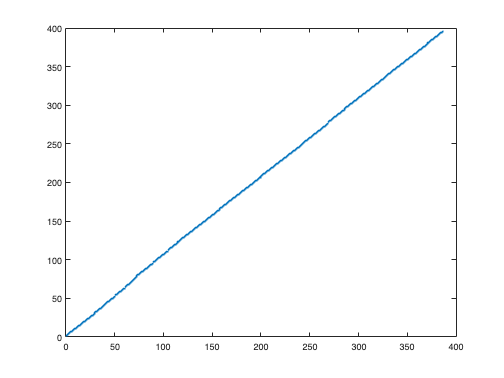

data_plot = data_dilcorr(:,mass_plot) ; 
T = cluster(Z,"maxclust",10) ;
%plot native
plot(mass_plot,'.')

#### **ensure correct range selected for clustering dendogram**

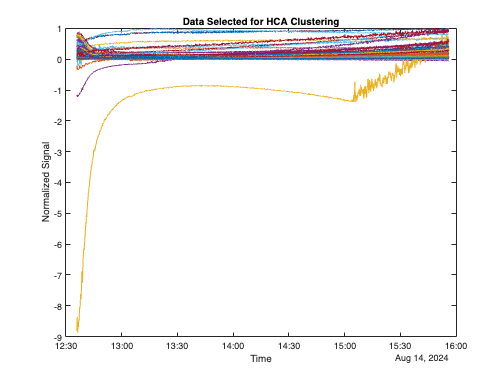

figure;
plot(time1_bgv(ind_lighton:ind_sample_end), hca_traces);
xlabel('Time');
ylabel('Normalized Signal');
title('Data Selected for HCA Clustering');

# **CLUSTER 1**

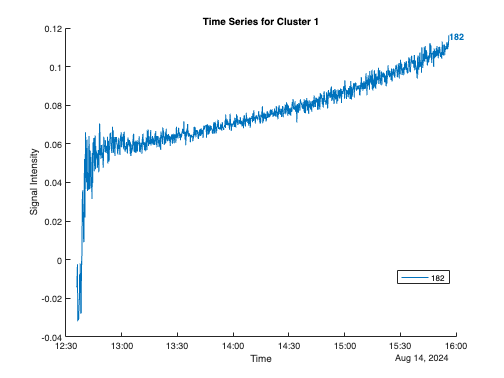

cluster_num = 1;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

# **CLUSTER 2**

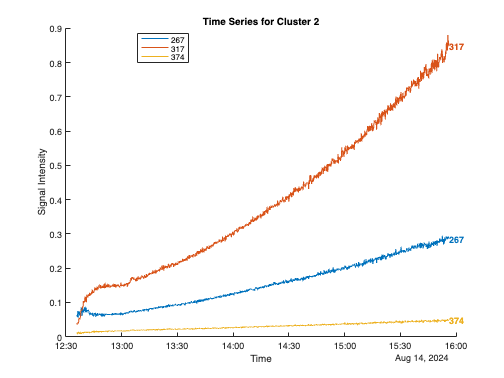

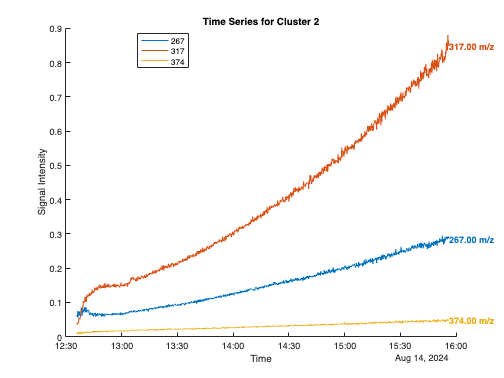

cluster_num = 2;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

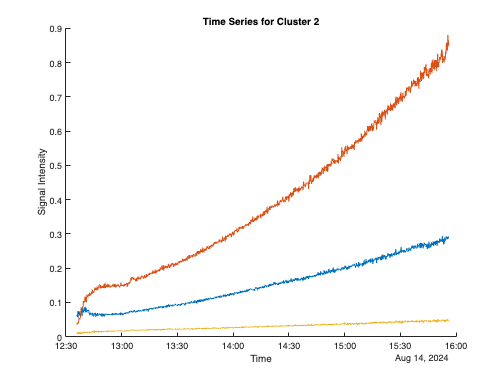

cluster_num = 2;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);

hold off

# **CLUSTER 3**

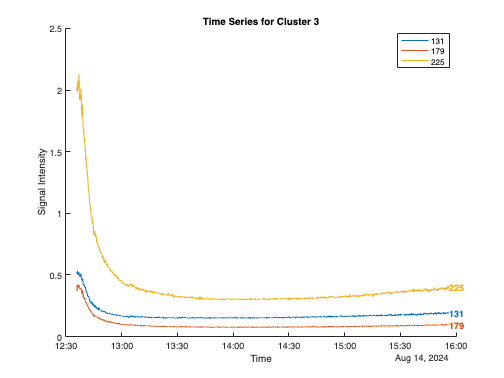

cluster_num = 3;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

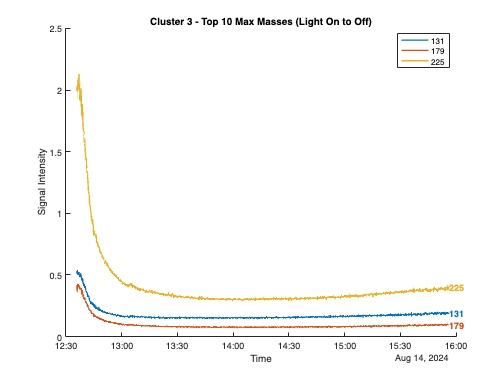

%%TOP 10 MASSES


cluster_num = 3;  
ind_cluster = find(T == cluster_num);  

% MASSES + SIGNAL FOR THIA CLUSTER
mass_cluster = mass_plot(ind_cluster); 

% MAX INTENSITIES FOR RANGE
data_cluster_range = data_plot(ind_lighton:ind_sample_end, ind_cluster);
max_intensities = maxk(max(data_cluster_range), 10); 

% INDICES TOP 10 MAAWA
[~, max_masses_ind] = maxk(max_intensities, 10);  

% TOP MAAWA + SIGNALA
top_masses = mass_cluster(max_masses_ind);  
top_signals = data_cluster_range(:, max_masses_ind); 

% DEFINE TIME RANGE
time_cluster = time1_bgv(ind_lighton:ind_sample_end);

% PLOT TOP 10 MASSES IN SPECIFIC TIME RANGE
figure;
hold on;
colors = lines(length(top_masses)); 

for i = 1:length(top_masses)
    plot(time_cluster, top_signals(:, i), 'Color', colors(i, :), 'LineWidth', 1.5);
    text(time_cluster(end), top_signals(end, i), num2str(top_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Cluster ', num2str(cluster_num), ' - Top 10 Max Masses (Light On to Off)']);
legend(arrayfun(@num2str, top_masses, 'UniformOutput', false), 'Location', 'best');
hold off;

# **CLUSTER 4**

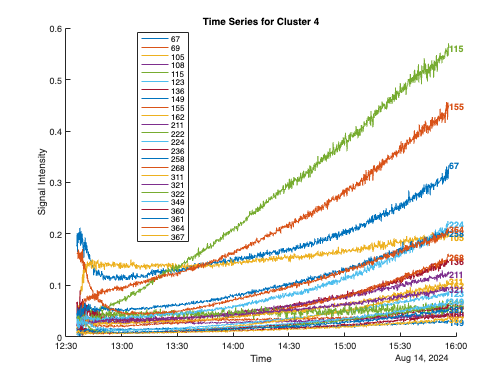

cluster_num = 4;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

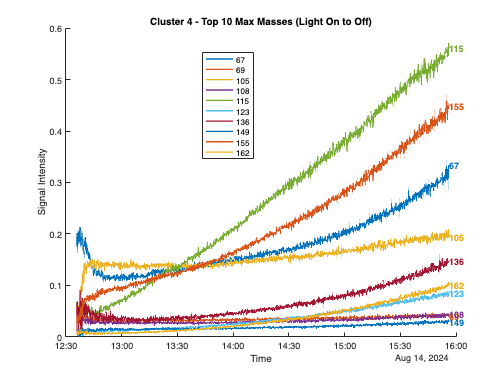

%%TOP 10 MASSES


cluster_num = 4;  
ind_cluster = find(T == cluster_num);  

% MASSES + SIGNAL FOR THIA CLUSTER
mass_cluster = mass_plot(ind_cluster); 

% MAX INTENSITIES FOR RANGE
data_cluster_range = data_plot(ind_lighton:ind_sample_end, ind_cluster);
max_intensities = maxk(max(data_cluster_range), 10); 

% INDICES TOP 10 MAAWA
[~, max_masses_ind] = maxk(max_intensities, 10);  

% TOP MAAWA + SIGNALA
top_masses = mass_cluster(max_masses_ind);  
top_signals = data_cluster_range(:, max_masses_ind); 

% DEFINE TIME RANGE
time_cluster = time1_bgv(ind_lighton:ind_sample_end);

% PLOT TOP 10 MASSES IN SPECIFIC TIME RANGE
figure;
hold on;
colors = lines(length(top_masses)); 

for i = 1:length(top_masses)
    plot(time_cluster, top_signals(:, i), 'Color', colors(i, :), 'LineWidth', 1.5);
    text(time_cluster(end), top_signals(end, i), num2str(top_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Cluster ', num2str(cluster_num), ' - Top 10 Max Masses (Light On to Off)']);
legend(arrayfun(@num2str, top_masses, 'UniformOutput', false), 'Location', 'best');
hold off;

# **CLUSTER 5**

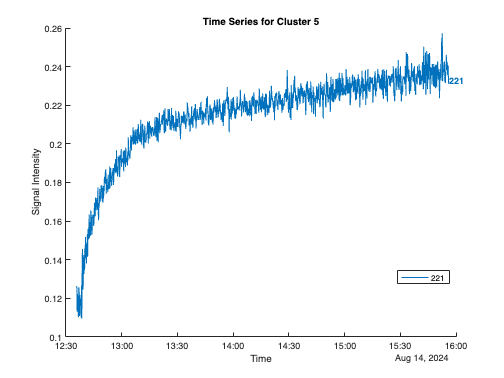

cluster_num = 5;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

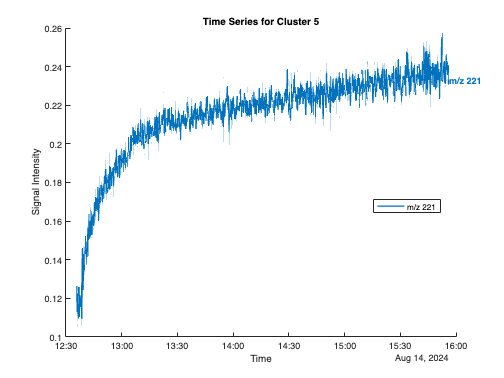

% Define the cluster number
cluster_num = 5;  
ind_cluster = find(T == cluster_num);  

% Get the correct mass-to-charge ratios (m/z) for the cluster
cluster_masses = mass_plot(ind_cluster); 

% Restrict to the light-on to before zero-air period
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

% Plotting with proper m/z labels
figure;
hold on;
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :), 'LineWidth', 1.5); 
    
    % Ensure the displayed text is the m/z value, not a peak intensity or index
    text(time_cluster(end), data_cluster(end, i), ...
        sprintf('m/z %.0f', cluster_masses(i)), ... % Force it to show as a proper mass
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(arrayfun(@(x) sprintf('m/z %.0f', x), cluster_masses, 'UniformOutput', false), ...
       'Location', 'best');  
hold off;

# **CLUSTER 6**

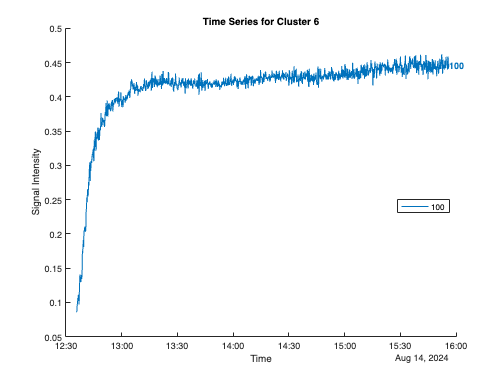

cluster_num = 6;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

# **CLUSTER 7**

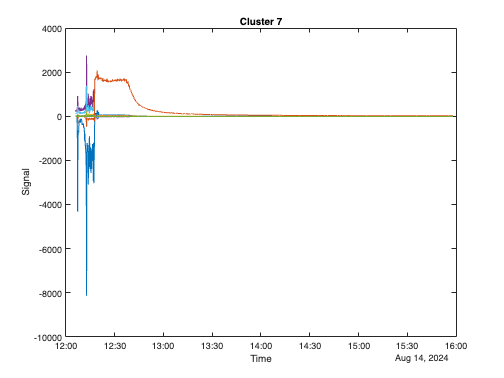

%plot inline
ind7 = find(T == 7) ; 
plot(time1_bgv,data_plot(:,ind7))
xlabel('Time') 
ylabel('Signal') 
title('Cluster 7')

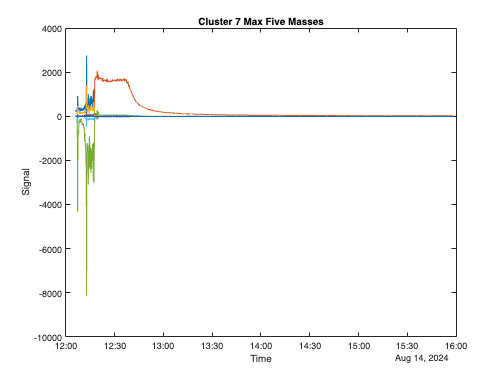

max_ind7 = maxk(data_plot(:,ind7),1) ; 
[test,max_masses_ind7a] = maxk(max_ind7,50) ; 
mass7 = mass_plot(ind7) ; 
plot(time1_bgv,data_plot(:,ind7(max_masses_ind7a)))
xlabel('Time') 
ylabel('Signal') 
title('Cluster 7 Max Five Masses')

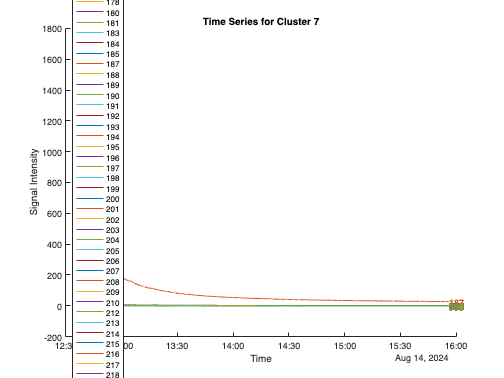

cluster_num = 7;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

disp(['Cluster 7 contains ', num2str(length(ind_cluster)), ' elements.']);

Cluster 7 contains 348 elements.


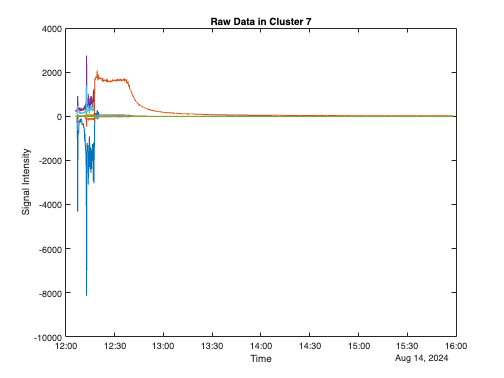

figure;
plot(time1_bgv, data_plot(:, ind_cluster));
xlabel('Time');
ylabel('Signal Intensity');
title('Raw Data in Cluster 7');

# **CLUSTER 8**

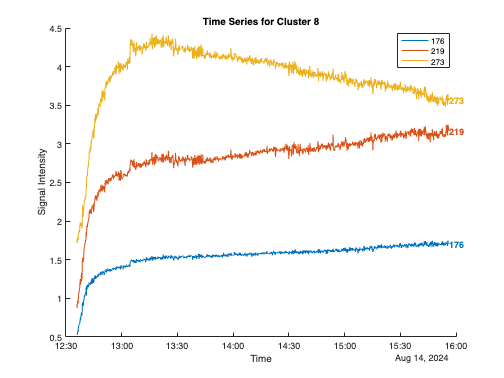

cluster_num = 8;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

disp(['Cluster 8 contains ', num2str(length(ind_cluster)), ' elements.']);

Cluster 8 contains 3 elements.


# **CLUSTER 9**

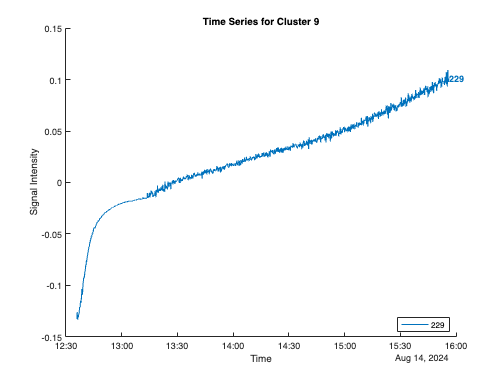

cluster_num = 9;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

# **CLUSTER 10**

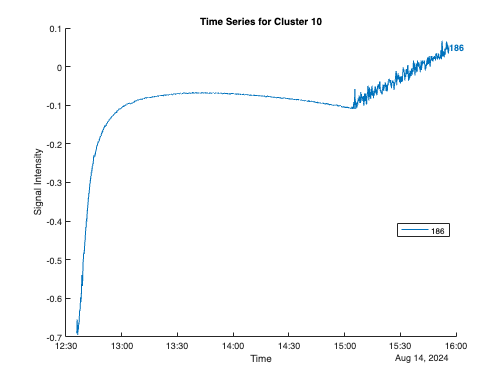

cluster_num = 10;  
ind_cluster = find(T == cluster_num);  
cluster_masses = mass_plot(ind_cluster); 

% ONLY LIGHT ON TO BEFORE ZERO AIR
time_cluster = time1_bgv(ind_lighton:ind_sample_end);
data_cluster = data_plot(ind_lighton:ind_sample_end, ind_cluster);

figure;
hold on
colors = lines(length(ind_cluster)); 

for i = 1:length(ind_cluster)
    plot(time_cluster, data_cluster(:, i), 'Color', colors(i, :)); 
    text(time_cluster(end), data_cluster(end, i), num2str(cluster_masses(i)), ...
        'Color', colors(i, :), 'FontSize', 10, 'FontWeight', 'bold'); 
end

xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Cluster ', num2str(cluster_num)]);
legend(string(cluster_masses), 'Location', 'best');  
hold off

% Define the target m/z ratio
target_mz = 130;

% Find the index of the target m/z in mass_plot or all_Mx_data_HR
[~, target_index] = min(abs(mass_plot - target_mz));

% Verify the selected mass
disp(['Selected m/z: ', num2str(mass_plot(target_index))]);

Selected m/z: 130


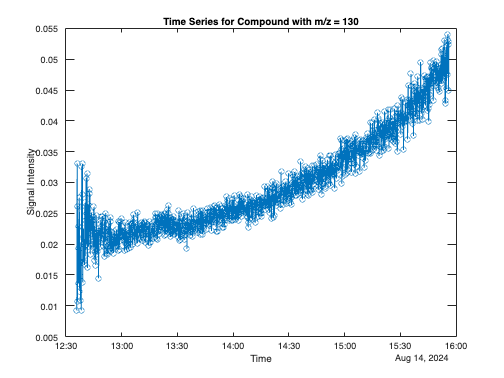


% Extract time and intensity data for the target compound
time_target = time1_bgv(ind_lighton:ind_sample_end);
data_target = data_plot(ind_lighton:ind_sample_end, target_index);

% Plot the time series for the target compound
figure;
plot(time_target, data_target, '-o');
xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Compound with m/z = ', num2str(mass_plot(target_index))]);


% Define the target m/z ratio
target_mz = 118;

% Find the index of the target m/z in mass_plot or all_Mx_data_HR
[~, target_index] = min(abs(mass_plot - target_mz));

% Verify the selected mass
disp(['Selected m/z: ', num2str(mass_plot(target_index))]);

Selected m/z: 118


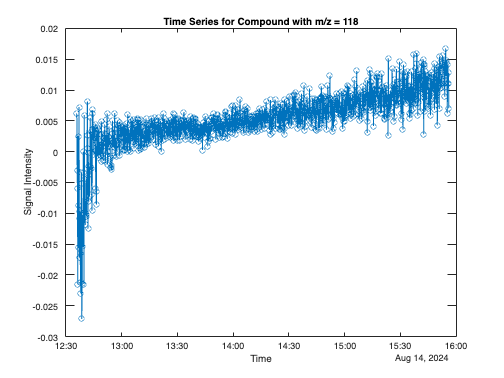


% Extract time and intensity data for the target compound
time_target = time1_bgv(ind_lighton:ind_sample_end);
data_target = data_plot(ind_lighton:ind_sample_end, target_index);

% Plot the time series for the target compound
figure;
plot(time_target, data_target, '-o');
xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Compound with m/z = ', num2str(mass_plot(target_index))]);

% Define the target m/z ratio
target_mz = 162;

% Find the index of the target m/z in mass_plot or all_Mx_data_HR
[~, target_index] = min(abs(mass_plot - target_mz));

% Verify the selected mass
disp(['Selected m/z: ', num2str(mass_plot(target_index))]);

Selected m/z: 162


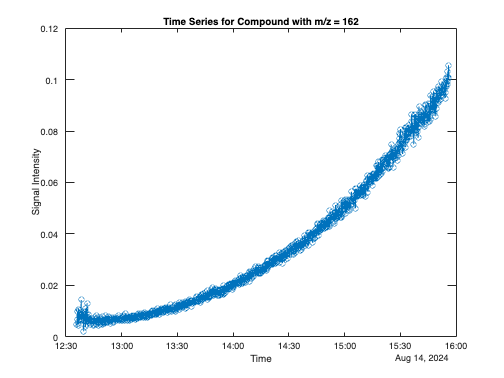


% Extract time and intensity data for the target compound
time_target = time1_bgv(ind_lighton:ind_sample_end);
data_target = data_plot(ind_lighton:ind_sample_end, target_index);

% Plot the time series for the target compound
figure;
plot(time_target, data_target, '-o');
xlabel('Time');
ylabel('Signal Intensity');
title(['Time Series for Compound with m/z = ', num2str(mass_plot(target_index))]);

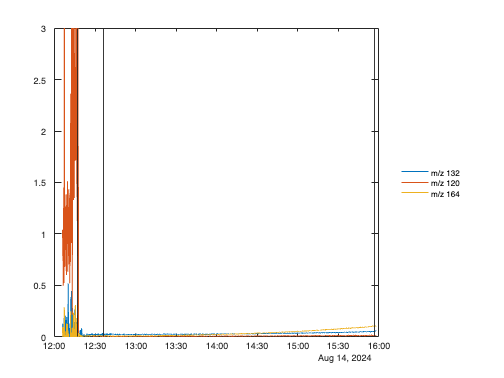

%plot inline
plot(time1_bgv,data_dilcorr(:,130)) % Ether 
hold on
plot(time1_bgv,data_dilcorr(:,118)) % ROOH
plot(time1_bgv,data_dilcorr(:,162)) % Carbonyl (Acetone)
xline(datetime(inject2_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
xline(datetime(lighton_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
xline(datetime(lightoff_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
legend('m/z 92','m/z 94','m/z 76','m/z 136','m/z 61','box','off','location','eastoutside') 
ylim([0 3])
%plot inline

xline(datetime(inject2_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
xline(datetime(lighton_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
xline(datetime(lightoff_time,'InputFormat','MM/dd/uuuu HH:mm:ss.SSS'))
legend('m/z 132','m/z 120','m/z 164','box','off','location','eastoutside') 
ylim([0 3])

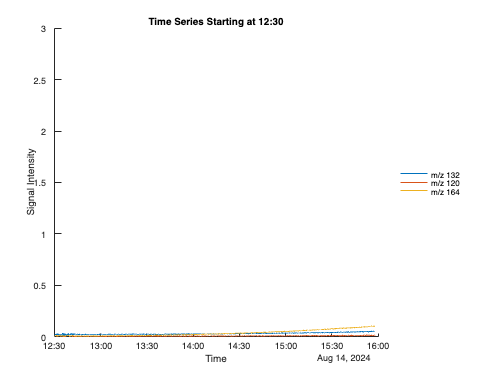

% start tiome for plot: after lights turned on
start_time = datetime('08/14/2024 12:30:00.000', 'InputFormat', 'MM/dd/uuuu HH:mm:ss.SSS');

%  index where the time is greater than or equal to 12:30
start_index = find(time1_bgv >= start_time, 1, 'first');

% plot data starting from the start_index
figure;
hold on;

% plot the data for selected masses
plot(time1_bgv(start_index:end), data_dilcorr(start_index:end, 130)) % Ether
plot(time1_bgv(start_index:end), data_dilcorr(start_index:end, 118)) % ROOH
plot(time1_bgv(start_index:end), data_dilcorr(start_index:end, 162)) % Carbonyl (Acetone)



% legend/labels
legend('m/z 132', 'm/z 120', 'm/z 164','box', 'off', 'location', 'eastoutside');
xlabel('Time');
ylabel('Signal Intensity');
title('Time Series Starting at 12:30');
ylim([0 3]);
hold off;